mystartdefaults
num_method_final

discrete_bound1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


discrete_bound2 =    65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74.5000   75.0000   75.5000   76.0000   76.5000   77.0000   77.5000   78.0000   78.5000   79.0000   79.5000   80.0000


Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 150.411749 eV


discrete_bound1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


discrete_bound2 =    65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74.5000   75.0000   75.5000   76.0000   76.5000   77.0000   77.5000   78.0000   78.5000   79.0000   79.5000   80.0000


Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 150.411749 eV


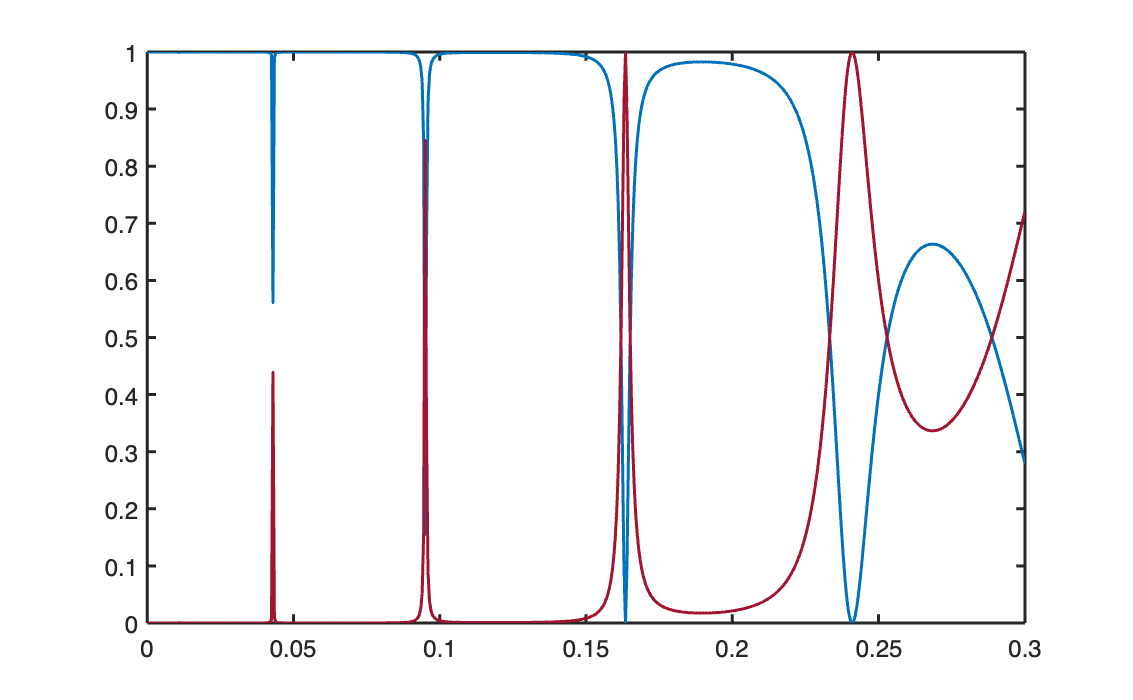

question_2

Question 5

% Energy range and step size
E_min = 0; % in eV
E_max = 0.3; % in eV
deltaE = 0.0005; % in eV

% Recombination time (lifetime)
tau = 1e-9; % 1 ns in seconds

% Array of energy values
% Energy E0
E0 = E_min:deltaE:E_max;
R_values_01 = zeros(length(E0), 1);
T_values_01 = zeros(length(E0), 1);
A_values_01 = zeros(length(E0), 1);
% Space discretization inside potentials
% Inside U1
x1_min = 0;
x1_max = 80;

n = (x1_max - x1_min)/step_size;

U = zeros(n, 1); % Potential barrier
x1 = zeros(n, 1);

for i = 1:n
    x1(i) = x1_min + step_size/2 + (i - 1) * step_size;
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.1;
    else
        U(i) = 0;
    end
    V(i) = U(i) / ekinscale;
end

Defining parameters

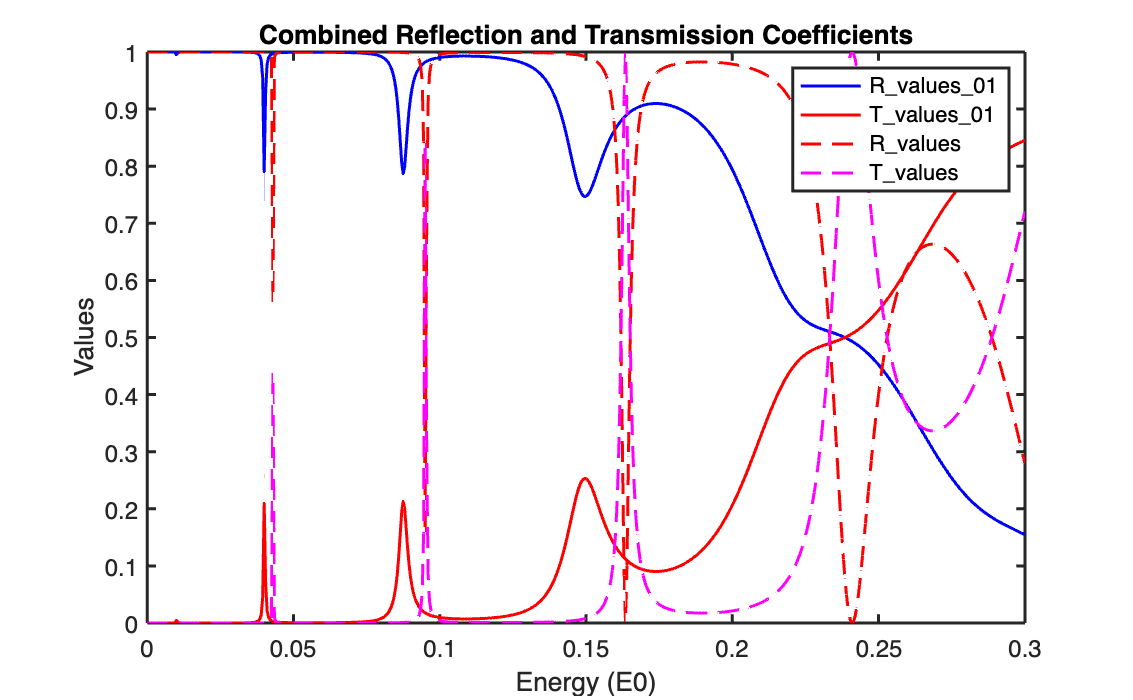

k_0 = zeros(1, length(E0));
lmbda = zeros(1, length(E0));
for i = 1:length(E0)
    k_0(i) = sqrt(E0(i) / ekinscale);
    lmbda(i) = 2 * pi / k_0(i);
end

m = 2;
x = zeros(m, 1);
Phis = zeros(m, 1);
Phi = zeros(m, 1);
x(1) = x1_min - 1;
x(2) = x1_max + 1;

%fprintf('    n           k             E0                R             T              R+T\n');
for k = 1:length(E0)
    if E0(k) == 0
        R_values_01(k) = 1;
        T_values_01(k) = 0;
        A_values_01(k) = 0;
    else
        Phi0p = exp(1i * k_0(k) * x1);
        G0 = zeros(n, n);
        for j = 1:n
            for i = 1:n
                G0(i, j) = step_size * exp(1i * k_0(k) * abs(x1(i) - x1(j))) / (2i * k_0(k));
            end
        end

        T = eye(n) - G0 * diag(V);
        Phip = T \ Phi0p;

        for i = 1:m
            Phis(i) = 0;
            for j = 1:n
                Phis(i) = Phis(i) + step_size * (exp(1i * k_0(k) * abs(x(i) - x1(j)))) / (2 * 1i * k_0(k)) * V(j) * Phip(j);
            end
        end
        Phi(i) = exp(1i * k_0(k) * x(i)) + Phis(i);
        R_values_01(k) = abs(Phis(1) / exp(1i * k_0(k) * x(1)))^2;
        T_values_01(k) = abs(Phi(2))^2;
        A_values_01(k) = 1 - R_values_01(k) - T_values_01(k);
    end
    %fprintf('%4d %15.3E %15.3E %15.3E %15.3E %15.3E\n', k, k_0(k), E0(k), R_values(k), T_values(k), A_values(k));
end
% Create a new figure
figure;

% Plot the first set of data
plot(E0, R_values_01, 'b'); % Choose a color (e.g., 'b' for blue)
hold on; % Retain the current plot when adding new plots
plot(E0, T_values_01, 'r'); % Choose a different color (e.g., 'r' for red)

% Plot the second set of data
plot(E0, R_values, 'r--'); % Different color and line style (e.g., 'g--' for dashed green)
plot(E0, T_values, 'm--'); % Different color and line style (e.g., 'm--' for dashed magenta)

% Add labels, title, and legend
xlabel('Energy (E0)');
ylabel('Values');
title('Combined Reflection and Transmission Coefficients');
legend('R\_values\_01', 'T\_values\_01', 'R\_values', 'T\_values');
hold off; % Release the plot hold